clear

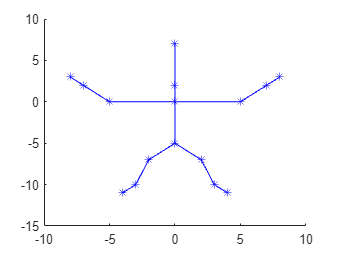

% Section1: build skeleton
head = [0, 0; 2, 7];
neck = [0, 0; 0, 2];
left_upper_arm = [0, -5; 0, 0];
left_forearm = [-5, -7; 0, 2];
left_hand = [-7, -8; 2, 3];
right_upper_arm = [0, 5; 0, 0];
right_forearm = [5, 7; 0, 2];
right_hand = [7, 8; 2, 3];
body = [0, 0; 0, -5];
left_thigh = [0, -2; -5, -7];
left_lower_leg = [-2, -3; -7, -10];
left_feet = [-3, -4; -10, -11];
right_thigh = [0, 2; -5, -7];
right_lower_leg = [2, 3; -7, -10];
right_feet = [3, 4; -10, -11];
skeleton = {head, neck, left_upper_arm, left_forearm, left_hand, right_upper_arm, right_forearm, right_hand, body, left_thigh, left_lower_leg, left_feet, right_thigh, right_lower_leg, right_feet};

% plot
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

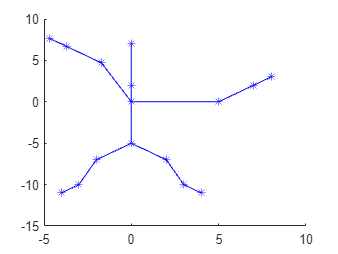

%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Section2: rotate left_upper_arm, left_forearm and left_hand
%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Enter your code here
%Each part should allow a changeable rotation angle.
theta3 = -70;   %left upper arm
%part1:left upper arm->3
%rotate the left upper arm->3;
%define function Rotate_and_update->update the coords of skeleton(3) by using the theta
updated_3 = Rotate_and_update(skeleton(3),theta3);
%update the coords of left_forearm->(4) and left_hand->(5)
difference = cell2mat(updated_3) - cell2mat(skeleton(3));
skeleton(4) = mat2cell(cell2mat(skeleton(4)) + difference(:,2), ...
                        size(cell2mat(skeleton(4)), 1), ...
                        size(cell2mat(skeleton(4)), 2));
skeleton(5) = mat2cell(cell2mat(skeleton(5)) + difference(:,2), ...
                        size(cell2mat(skeleton(5)), 1), ...
                        size(cell2mat(skeleton(5)), 2));
%update the coords of left upper arm->3
skeleton(3) = updated_3;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

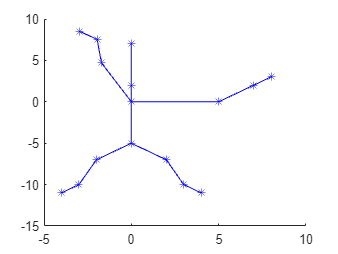


theta4 = -40;%left_forearm
%part2:left_forearm->4
%define function Rotate_and_update->update the coords of skeleton(4) by using the theta
updated_4 = Rotate_and_update(skeleton(4),theta4);
%update the coords of  left_hand->(5)
difference = cell2mat(updated_4) - cell2mat(skeleton(4));
skeleton(5) = mat2cell(cell2mat(skeleton(5)) + difference(:,2), ...
                        size(cell2mat(skeleton(5)), 1), ...
                        size(cell2mat(skeleton(5)), 2));
%update the coords of left_forearm->4
skeleton(4) = updated_4;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

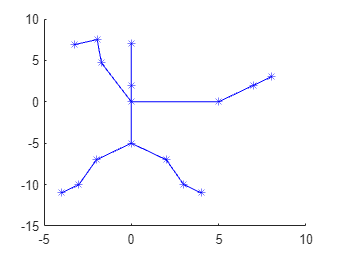


theta5 = 70;    %left_hand
%part3:left_hand->(5)
%define function Rotate_and_update->update the coords of skeleton(5) by using the theta
updated_5 = Rotate_and_update(skeleton(5),theta5);
%update the coords of left_forearm->4
skeleton(5) = updated_5;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

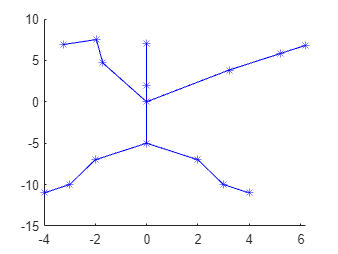

%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Section3: rotate right_upper_arm, right_forearm and right_hand
%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Enter your code here
%Each part should allow a changeable rotation angle.
theta6 = 50;   %right_upper_arm
%part1:right_upper_arm->6
%rotate right_upper_arm->6;
%define function Rotate_and_update->update the coords of skeleton(6) by using the theta
updated_6 = Rotate_and_update(skeleton(6),theta6);
%update the coords of right_forearm->(7) and right_hand->(8)
difference = cell2mat(updated_6) - cell2mat(skeleton(6));
skeleton(7) = mat2cell(cell2mat(skeleton(7)) + difference(:,2), ...
                        size(cell2mat(skeleton(7)), 1), ...
                        size(cell2mat(skeleton(7)), 2));
skeleton(8) = mat2cell(cell2mat(skeleton(8)) + difference(:,2), ...
                        size(cell2mat(skeleton(8)), 1), ...
                        size(cell2mat(skeleton(8)), 2));
%update the coords of right_upper_arm->6
skeleton(6) = updated_6;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

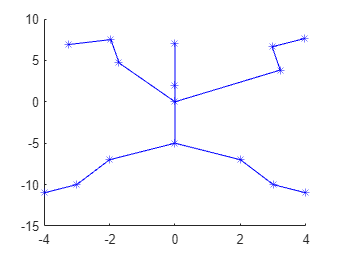


theta7 = 50;%right_forearm
%part2:right_forearm->7
%define function Rotate_and_update->update the coords of skeleton(7) by using the theta
updated_7 = Rotate_and_update(skeleton(7),theta7);
%update the coords of  right_hand->(8)
difference = cell2mat(updated_7) - cell2mat(skeleton(7));
skeleton(8) = mat2cell(cell2mat(skeleton(8)) + difference(:,2), ...
                        size(cell2mat(skeleton(8)), 1), ...
                        size(cell2mat(skeleton(8)), 2));
%update the coords of right_forearm->7
skeleton(7) = updated_7;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

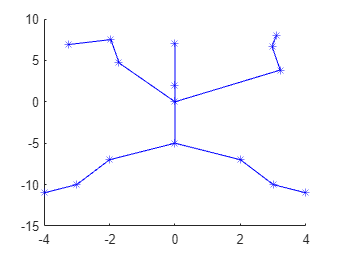


theta8 = 40;    %right_hand
%part3:right_hand->(8)
%define function Rotate_and_update->update the coords of skeleton(8) by using the theta
updated_8 = Rotate_and_update(skeleton(8),theta8);
%update the coords of right_hand->8
skeleton(8) = updated_8;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

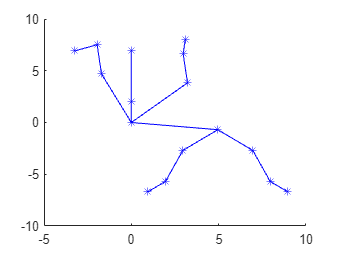

%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Section4: rotate the body and update the related body part
%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
%figure for this section. 
% Enter your code here
%Each part should allow a changeable rotation angle.
theta9 = 82;   %body
%part1:body->9
%rotate body->9;
%define function Rotate_and_update->update the coords of skeleton(9) by using the theta
updated_9 = Rotate_and_update(skeleton(9),theta9);
%update the coords of left_thigh->10, left_lower_leg->11, left_feet->12,
%right_thigh->13, right_lower_leg->14, right_feet->15
difference = cell2mat(updated_9) - cell2mat(skeleton(9));
skeleton(10) = mat2cell(cell2mat(skeleton(10)) + difference(:,2), ...
                        size(cell2mat(skeleton(10)), 1), ...
                        size(cell2mat(skeleton(10)), 2));
skeleton(11) = mat2cell(cell2mat(skeleton(11)) + difference(:,2), ...
                        size(cell2mat(skeleton(11)), 1), ...
                        size(cell2mat(skeleton(11)), 2));
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + difference(:,2), ...
                        size(cell2mat(skeleton(12)), 1), ...
                        size(cell2mat(skeleton(12)), 2));
skeleton(13) = mat2cell(cell2mat(skeleton(13)) + difference(:,2), ...
                        size(cell2mat(skeleton(13)), 1), ...
                        size(cell2mat(skeleton(13)), 2));
skeleton(14) = mat2cell(cell2mat(skeleton(14)) + difference(:,2), ...
                        size(cell2mat(skeleton(14)), 1), ...
                        size(cell2mat(skeleton(14)), 2));
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + difference(:,2), ...
                        size(cell2mat(skeleton(15)), 1), ...
                        size(cell2mat(skeleton(15)), 2));

%update the coords of right_upper_arm->6
skeleton(9) = updated_9;

% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

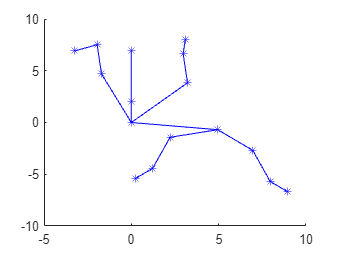

%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Section5: rotate left_thigh, left_lower_leg and left_feet
%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Enter your code here
%Each part should allow a changeable rotation angle.
theta10 = -30;   %left_thigh
%part1:left_thigh->10
%rotate left_thigh->10;
%define function Rotate_and_update->update the coords of skeleton(10) by using the theta
updated_10 = Rotate_and_update(skeleton(10),theta10);
%update the coords of left_lower_leg->(11) and left_feet->(12)
difference = cell2mat(updated_10) - cell2mat(skeleton(10));
skeleton(11) = mat2cell(cell2mat(skeleton(11)) + difference(:,2), ...
                        size(cell2mat(skeleton(11)), 1), ...
                        size(cell2mat(skeleton(11)), 2));
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + difference(:,2), ...
                        size(cell2mat(skeleton(12)), 1), ...
                        size(cell2mat(skeleton(12)), 2));
%update the coords of left_thigh->10
skeleton(10) = updated_10;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

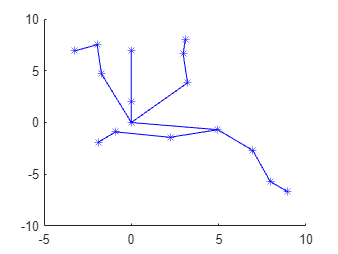

theta11 = -81;%left_lower_leg
%part2:left_lower_leg->11
%define function Rotate_and_update->update the coords of skeleton(11) by using the theta
updated_11 = Rotate_and_update(skeleton(11),theta11);
%update the coords of  left_feet->(12)
difference = cell2mat(updated_11) - cell2mat(skeleton(11));
skeleton(12) = mat2cell(cell2mat(skeleton(12)) + difference(:,2), ...
                        size(cell2mat(skeleton(12)), 1), ...
                        size(cell2mat(skeleton(12)), 2));
%update the coords of left_lower_leg->11
skeleton(11) = updated_11;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

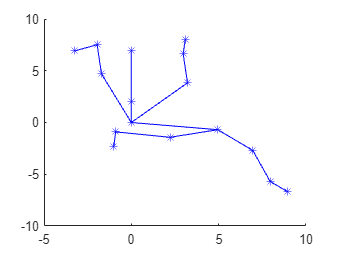

theta12 = 41;    %left_feet
%part3:left_feet->(12)
%define function Rotate_and_update->update the coords of skeleton(12) by using the theta
updated_12 = Rotate_and_update(skeleton(12),theta12);
%update the coords of left_feet->12
skeleton(12) = updated_12;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

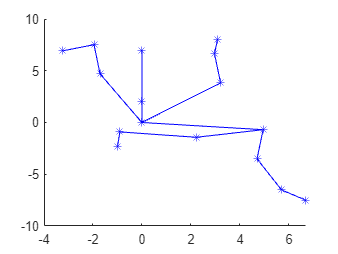

%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Section6: rotate right_thigh, right_lower_leg and right_feet
%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Enter your code here
%Each part should allow a changeable rotation angle.
theta13 = -50;   %right_thigh
%part1:right_thigh->13
%rotate right_thigh->13;
%define function Rotate_and_update->update the coords of skeleton(13) by using the theta
updated_13 = Rotate_and_update(skeleton(13),theta13);
%update the coords of right_lower_leg->(14) and right_feet->(15)
difference = cell2mat(updated_13) - cell2mat(skeleton(13));
skeleton(14) = mat2cell(cell2mat(skeleton(14)) + difference(:,2), ...
                        size(cell2mat(skeleton(14)), 1), ...
                        size(cell2mat(skeleton(14)), 2));
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + difference(:,2), ...
                        size(cell2mat(skeleton(15)), 1), ...
                        size(cell2mat(skeleton(15)), 2));
%update the coords of right_thigh->13
skeleton(13) = updated_13;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

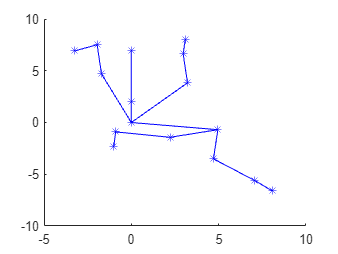


theta14 = 30;%right_lower_leg
%part2:right_lower_leg->14
%define function Rotate_and_update->update the coords of skeleton(14) by using the theta
updated_14 = Rotate_and_update(skeleton(14),theta14);
%update the coords of  right_feet->(15)
difference = cell2mat(updated_14) - cell2mat(skeleton(14));
skeleton(15) = mat2cell(cell2mat(skeleton(15)) + difference(:,2), ...
                        size(cell2mat(skeleton(15)), 1), ...
                        size(cell2mat(skeleton(15)), 2));
%update the coords of right_lower_leg->11
skeleton(14) = updated_14;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

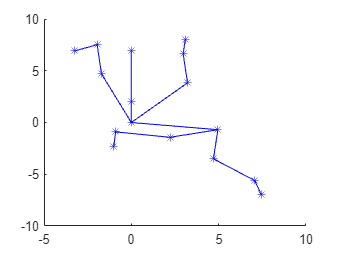

theta15 = -30;    %right_feet
%part3:left_feet->(15)
%define function Rotate_and_update->update the coords of skeleton(15) by using the theta
updated_15 = Rotate_and_update(skeleton(15),theta15);
%update the coords of left_feet->12
skeleton(15) = updated_15;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

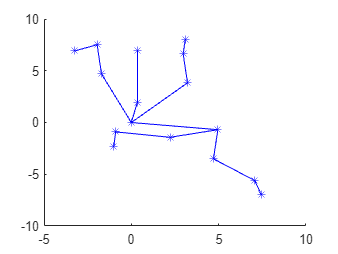

%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Section7: rotate head and neck
%+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
% Enter your code here
%Each part should allow a changeable rotation angle.
theta2 = -10;   %head
%part1:neck->2
%rotate neck->2;
%define function Rotate_and_update->update the coords of skeleton(2) by using the theta
updated_2 = Rotate_and_update(skeleton(2),theta2);
%update the coords of head->(1)
difference = cell2mat(updated_2) - cell2mat(skeleton(2));
skeleton(1) = mat2cell(cell2mat(skeleton(1)) + difference(:,2), ...
                        size(cell2mat(skeleton(1)), 1), ...
                        size(cell2mat(skeleton(1)), 2));
%update the coords of neck->2
skeleton(2) = updated_2;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

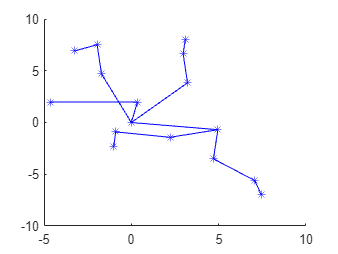


theta1 = 90;%neck
%part2:head->1
%define function Rotate_and_update->update the coords of skeleton(1) by using the theta
updated_1 = Rotate_and_update(skeleton(1),theta1);
%update the coords of head->1
skeleton(1) = updated_1;
% Plot the result
% Enter your code here
clf
figure(1)
hold on;
for i = 1:15
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

function Rotation_Matrix = Rotation(theta)
    %change degree to rad
    rad = deg2rad(theta);
    Rotation_Matrix = [cos(rad),-sin(rad); sin(rad),cos(rad)];


end
function update = Rotate_and_update(skeleton, theta)
    % Convert angle from degrees to radians
    Rotation_M = Rotation(theta);
    % Extract original coordinates from the cell
    Ori = cell2mat(skeleton);
    % Translate part to origin for rotation
    coords = Ori - Ori(:,1);
    % Apply rotation
    r = Rotation_M * coords;
    % Translate part back
    update = r + Ori(:,1);
    % Convert back to cell
    update = mat2cell(update, size(update, 1), size(update, 2));
end

